dt = 1e-3; 
% t = t.Data; 

v = v_mPs.Data; 
a = a_mPs2.Data; 
j = gradient(a,dt);
F_friction_test = F_friction_N.Data + 16.5;
close all 

% --- Geçiş Yumuşaklığı Parametresi ---
% Bu değer büyüdükçe 0'daki eğim azalır (daha eğimli geçer)
eps_smooth = 0.00223;
% eps_smooth = 0.015;

% --- Pozitif Yön (v > 0) ---
kv_p = 39.658; Fc_p = 25; Fs_p = 82.9; tau_p = 0.0016;

% --- Negatif Yön (v < 0) ---
kv_n = 38.5; Fc_n = 5; Fs_n = 75.17; tau_n = 0.0016;

%%%
kv_p = 20; Fc_p = 38; Fs_p = 82.9; tau_p = 0.016;
kv_n = 35; Fc_n = 15; Fs_n = 75.17; tau_n = 0.016;
%%%

% Yumuşatılmış yön fonksiyonu (sign yerine tanh)
% Bu fonksiyon -1 ile 1 arasında yumuşak bir geçiş sağlar
smooth_sign = tanh(v ./ eps_smooth);

% Asimetrik katsayı vektörleri oluşturma
% Hızın yönüne göre katsayıları seçiyoruz
kv = (v >= 0)*kv_p + (v < 0)*kv_n;
Fc = (v >= 0)*Fc_p + (v < 0)*Fc_n;
Fs = (v >= 0)*Fs_p + (v < 0)*Fs_n;
tau = (v >= 0)*tau_p + (v < 0)*tau_n;
F_stribeck = (kv .* v) + (Fc .* smooth_sign) + (Fs .* smooth_sign .* exp(-abs(v./tau)));


K_acc = 1.121235; 
K_acc = 0.51121235; 

K_jerk = 0.056481; 
% K_jerk = 0.103256481; 
kappa_delay = 0; 

F_friction_nodelay = F_stribeck + K_acc * a  +  K_jerk*j; 

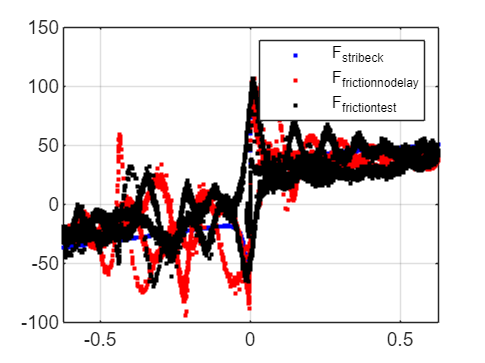

% figure
plot(v,F_stribeck,'.b')
hold on 
plot(v,F_friction_nodelay,'.r')
plot(v,F_friction_test,'.k')
grid on 
legend('F_stribeck','F_friction_nodelay','F_friction_test')

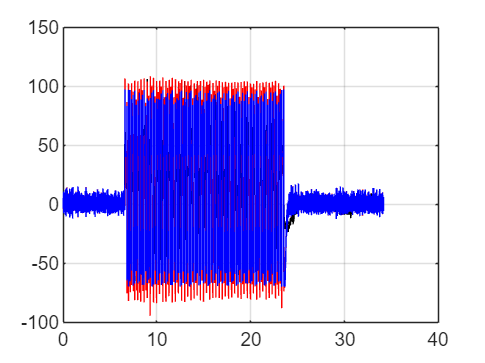

figure
plot(t.Time,F_friction_test,'-k')
hold on 
plot(t.Time,F_friction_nodelay,'-r')
plot(t.Time,F_stribeck,'-b')
grid on 